L=60 %[mm]

L = 60

 
z1=34

z1 = 34

z2=42

z2 = 42


%numarul de ordine i:
i=13

i = 13

 
%numarul de antrenori:
na=2

na = 2

 
%numarul de canale:
z=4

z = 4

 
ni=(55+7*i)*10 %[rad/min]

ni = 1460

 
%turatia motorului ni este egal cu n1:
n1=ni

n1 = 1460

n2=n1*z1/z2

n2 = 1.1819e+03


% n3 turatia antrenorului
n3=n2

n3 = 1.1819e+03

 


%1.Viteza unghiulara a elementului conducator:
w1=pi*n2/30

w1 = 123.7688

 
%2.Constanta mecanismului cu cruce de Malta:
lambda=sin(pi/z)

lambda = 0.7071

 
%3.Lungimea bratului de antrenare(raza elementului de antrenare):
R1=L*sin(pi/z)

R1 = 42.4264

 
%4.Timpul de miscare in care elementul conducator antreneaza elementul
%condus:
tm=(pi*(1-2/z))/w1

tm = 0.0127

 
%5.Timpul de repaus al elementului condus:
tr=(pi*(1+2/z))/w1

tr = 0.0381

 
%6.Timpul de rotatie completa:
T=tm+tr

T = 0.0508

 
%7.Coeficientul de miscare km:
km=tm/T

km = 0.2500

 
%8.Coeficientul de repaus kr:
kr=tr/T

kr = 0.7500

 
%9.Coeficientul timpului de lucru al mecanismului k:
k=km/kr

k = 0.3333



%%
phi = -pi/2:0.1:pi/2

phi =    -1.5708   -1.4708   -1.3708   -1.2708   -1.1708   -1.0708   -0.9708   -0.8708   -0.7708   -0.6708   -0.5708   -0.4708   -0.3708   -0.2708   -0.1708   -0.0708    0.0292    0.1292    0.2292    0.3292    0.4292    0.5292    0.6292    0.7292    0.8292    0.9292    1.0292    1.1292    1.2292    1.3292    1.4292    1.5292


%unghiul de rotatie al antrenorului:
phi1=-pi/2:0.01:pi/2 

phi1 =    -1.5708   -1.5608   -1.5508   -1.5408   -1.5308   -1.5208   -1.5108   -1.5008   -1.4908   -1.4808   -1.4708   -1.4608   -1.4508   -1.4408   -1.4308   -1.4208   -1.4108   -1.4008   -1.3908   -1.3808   -1.3708   -1.3608   -1.3508   -1.3408   -1.3308   -1.3208   -1.3108   -1.3008   -1.2908   -1.2808   -1.2708   -1.2608   -1.2508   -1.2408   -1.2308   -1.2208   -1.2108   -1.2008   -1.1908   -1.1808   -1.1708   -1.1608   -1.1508   -1.1408   -1.1308   -1.1208   -1.1108   -1.1008   -1.0908   -1.0808


%unghiul de rotatie al elem condus:
phi2=(zeros(length(phi),1)) ;
%acceleratia unghiulara a elem condus:
eps2=(zeros(length(phi),1)) ;
%viteza unghiulara a elementului condus:
w2=(zeros(length(phi),1));
 
w2max=(lambda/(1-lambda))*w3

w2max = 298.8043

epsi2=-w3^2*tan(pi/z)

epsi2 = -1.5319e+04

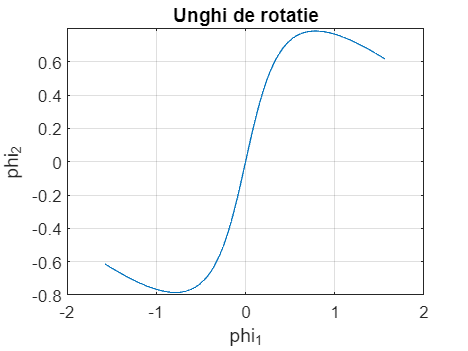

 
for i=1:length(phi1)
    phi2(i)=atan((lambda*sin(phi1(i)))/(1-lambda*cos(phi1(i))));
    eps2(i)=-((lambda*(1-lambda^2)*sin(phi1(i)))/((1-2*lambda*cos(phi1(i))+lambda^2)^2))*w3^2;
    w2(i)=(lambda*(cos(phi1(i))-lambda)/(1-2*lambda*cos(phi1(i))+lambda^2))*w3;
 
end
 
figure
%diagrama de variate a acceleratiei unghiulare
plot(phi1,phi2)
grid
xlabel('phi_1')
ylabel('phi_2')
title('Unghi de rotatie')

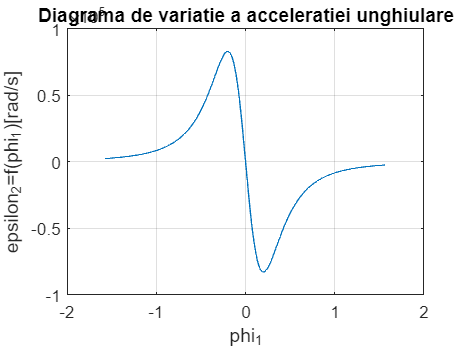


figure
%diagrama de variate a acceleratiei unghiulare
plot(phi1,eps2)
grid
xlabel('phi_1')
ylabel('epsilon_2=f(phi_1)[rad/s]')
title('Diagrama de variatie a acceleratiei unghiulare')

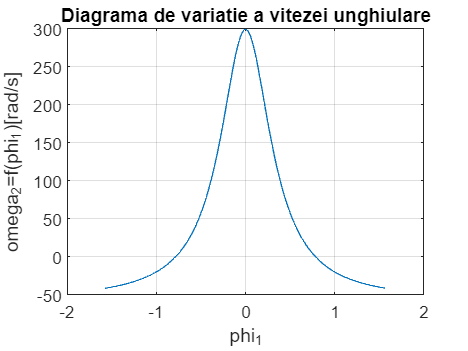

 
%diagrama de variatie a vitezei unghiulare:
figure 
plot(phi1,w2)
grid
xlabel('phi_1')
ylabel('omega_2=f(phi_1)[rad/s]')
title('Diagrama de variatie a vitezei unghiulare')